**Lab 7**

**Problem 1: ***Make a stacked histogram plot for the feature variable: mass*

Let's first reimport all of the data.

higgsData = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcdData = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
hPT = higgsData(1,:);
qPT = qcdData(1,:);

PT is the transverse (xy) momentum, given by pt = sqrt(px^2 + py^2), where px and py are the momenta along x and y.

hETA = higgsData(2,:);
qETA = qcdData(2,:);

ETA is the pseudorapidity, given by -ln(tan(ø/2))-0.5ln((abs(p)+pl)/(abs(p)-pl))

hPHI = higgsData(3,:);
qPHI = qcdData(3,:);

PHI is the azimuthal angle, given by arccos(x/r)

hMASS = higgsData(4,:);
qMASS = qcdData(4,:);

MASS is the mass invariant, given by E^2 = p^2 + m^2 (natural units).

hEE2 = higgsData(5,:);
qEE2 = qcdData(5,:);

EE2 is the 2-point ECF ratio, given by sum over i<j in J of (p_t,i * p_t,j * deltaR_ij * 1/(p_t,J)^2). This observable shows 2-prong particle decay.

hEE3 = higgsData(6,:);
qEE3 = qcdData(6,:);

EE3 is the 3-point ECF ratio, given by sum over i<j<k in J of (p_t,i * p_t,j * p_t,k * deltaR_ij * deltaR_ik * deltaR_jk * 1/(p_t,J)^3). This observable shows 3-prong particle decay.

hD2 = higgsData(7,:);
qD2 = qcdData(7,:);

D2 is the 3-to-2 point ECF ratio, given by EE3/(EE2)^3

hANG = higgsData(8,:);
qANG = qcdData(8,:);

ANG is the angularity, given by 1/m_J * sum over i in J of (E_i * cos^3(ø_i) / (sin^2(ø_i)))

hT1 = higgsData(9,:);
qT1 = qcdData(9,:);

T# variables are subjettiness, where # is the n in n-subjettiness, and Tnm is Tn/Tm.

hT2 = higgsData(10,:);
qT2 = qcdData(10,:);

hT3 = higgsData(11,:);
qT3 = qcdData(11,:);

hT21 = higgsData(12,:);
qT21 = qcdData(12,:);

hT32 = higgsData(13,:);
qT32 = qcdData(13,:);

hKTDELTAR = higgsData(14,:);
qKTDELTAR = qcdData(14,:);

Let's create a histogram plot containing both the background and the data of mass.

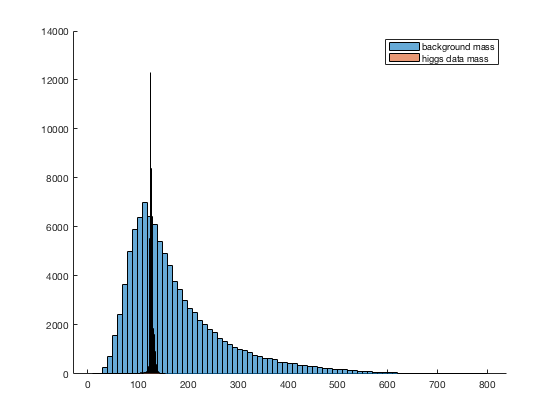

figure;
hold on
histogram(qMASS);
histogram(hMASS);
legend('background mass','higgs data mass');

*Evaluate expected significance without any event selection.*

*Use Poisson statistics for significance calculation.*

We are to assume that both of these follow a Poisson distribution. The statistics for the Poisson distributions in question are given in the "dataset" subsection of the assignment. For my data, N_higgs = 50, N_qcd = 2000.

N_higgs = 50;
N_qcd = 2000;
N_tot = N_higgs + N_qcd;

Make a poisson distribution centered on N_qcd, then find the significance of N_tot.

poissonQCD = makedist('Poisson',"lambda",N_qcd);
prob = 1 - cdf(poissonQCD,N_tot)

prob = 0.1296

s_Ntotqcd = icdf('Normal',1-prob,0,1)

s_Ntotqcd = 1.1282

The significance that I find for qcd is 1.13 sigma, which is not enough to claim a discovery. Let's compare this with the significance from the higgs.

poissonHiggs = makedist('Poisson',"lambda",N_higgs);
prob = 1 - cdf(poissonHiggs,N_tot)

prob = 0

s_Ntothiggs = icdf('Normal',1-prob,0,1)

s_Ntothiggs = Inf

This makes sense because the center is reeeally far away from the point we are evaluating.

*Compare your number of 𝑁𝐻𝑖𝑔𝑔𝑠/(√𝑁𝑄𝐶𝐷). If they are equivalent, explain your findings.*

N_higgs/sqrt(N_qcd)

ans = 1.1180

I actually don't understand what this question is asking me. N_higgs/sqrt(N_qcd) that I find is 1.12, which is different from the sigma we find above (and I don't see how they could be the same). I'm not sure what this number means, and so don't really understand what is meant by explaining my findings.

**Problem 2: ***Identify mass cuts to optimize the expected significance.*

*Try different mass cuts systematically*

*Evaluate expected significance for each set of mass cuts*

*Identify the set of the mass cuts which give you the highest significance.*

These directions are exceptionally awful. Literally nothing makes sense to me.

First, I think I need to calculate the total number of events in the background histogram, as well as the higgs data.

N_qcd_full = sum(qMASS(1,:))

N_qcd_full = 1.7727e+07

N_higgs_full = sum(hMASS(1,:))

N_higgs_full = 1.2666e+07

Now that I have the total number of events in the histograms, I want to select a range such that a lot of my higgs data is there, while trying to get as little of the background data as possible. I want to test a range somewhere between 100 and 150, so I will replot my histograms with that as the xlimit.

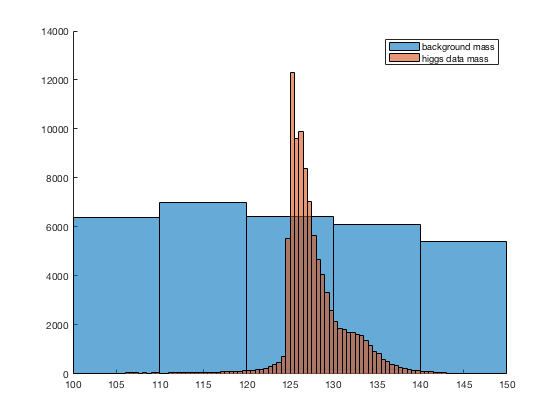

figure;
hold on
histogram(qMASS);
histogram(hMASS);
legend('background mass','higgs data mass');
xlim([100 150]);

From this plot, it looks like a range of 125-128 encapsulates a lot of the higgs data, and not so much of the background data. This is the "cut" that I want to evaluate.

For this "cut," I will calculate the number of higgs events present and the number of background events present.

N_qcd_range = sum(qMASS >= 125 & qMASS <= 128)

N_qcd_range = 1883

N_higgs_range = sum(hMASS >= 125 & hMASS <= 128)

N_higgs_range = 52894

These numbers seem a bit weird. I would have expected N_qcd_range to be a little bit higher, but N_higgs_range seems about right for the range specified.

Now, I need to create new Poisson distributions for this selected data range.

N_higgs_new = N_higgs * (N_higgs_range/N_higgs_full)

N_higgs_new = 0.2088

N_qcd_new = N_qcd * (N_qcd_range/N_qcd_full)

N_qcd_new = 0.2124

N_tot = N_higgs_new + N_qcd_new;
poissonQCD_range = makedist('Poisson',"lambda",N_qcd_new);
poissonHiggs_range = makedist('Poisson',"lambda",N_higgs_new);

Now, I want to calculate the significance again.

prob = 1 - cdf(poissonQCD_range,N_tot)

prob = 0.1914

s_rangeQCD = icdf('Normal',1-prob,0,1)

s_rangeQCD = 0.8728

prob = 1 - cdf(poissonHiggs_range,N_tot)

prob = 0.1884

s_rangeHiggs = icdf('Normal',1-prob,0,1)

s_rangeHiggs = 0.8837

Now these two significances are much more close, meaning that my signal selection was successful.

**Problem 3: ***Make stacked histogram plots for the reset of features*

*Set A of plots without any event selection*

*Can you identify another feature as discriminative as mass feature (i.e. equal or better significance after feature cut)*

*Set B of plots with your optimal mass cuts*

*Can you identify additional feature to further imrpove expected signifiance?*

**Problem 4: ***Optimize event selections using multiple features (if necessary)*

*Find a set of feature cuts which can help you to achieve the best significance.*

*Compare significance (before/after event selection) dervied in your pT samples to your lab partner. Describe your findings.*